# Plots

Laby Nicolas & Van Mechelen Alex

clc, clearvars
set(groot,'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(groot,'defaultLegendLocation','best')

# Basic Q-value algorithm

## 1 Example

exploration function = IdentityExplorationMethod

reward = loss*-100 + (number_of_completed_rows+above_row_completion)*500;

**float** gamma = 0.80f;*        // Discount factor*

**float** alpha = 0.02f;*        // Learning rate*

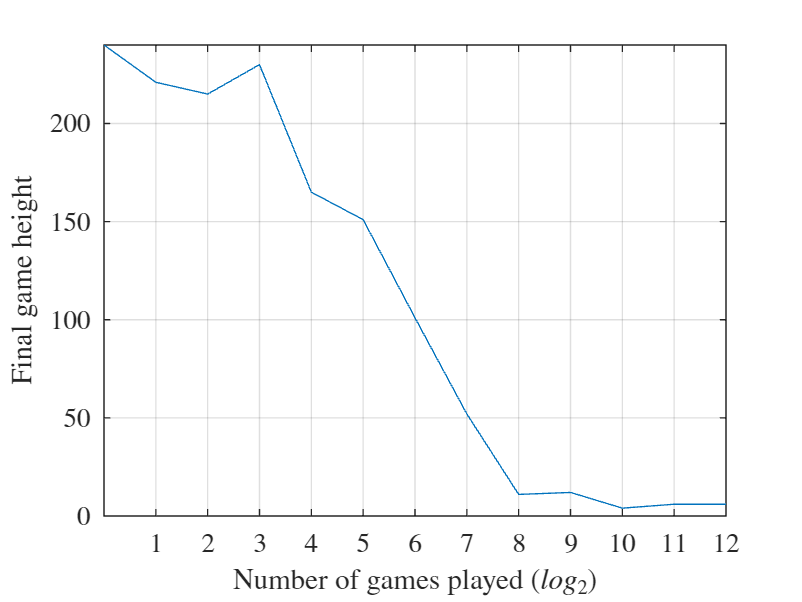

data1 = [1, 240, 0, 767
2, 221, 0, 1459
4, 215, 0, 2786
8, 230, 0, 5204
16, 165, 0, 9577
32, 151, 0, 16860
64, 101, 0, 28223
128, 52, 0, 44725
256, 11, 0, 66402
512, 12, 0, 91524
1024, 4, 0, 114256
2048, 6, 0, 134693
4096, 6, 0, 152489
8192, 4, 0, 166913];

subplot
plot(log2(data1(:,1)), data1(:,2))
grid on
xlabel("Number of games played ($log_2$)")
ylabel("Final game height")
xticks(1:12)
axis([0 12 0 max(data1(:,2))])

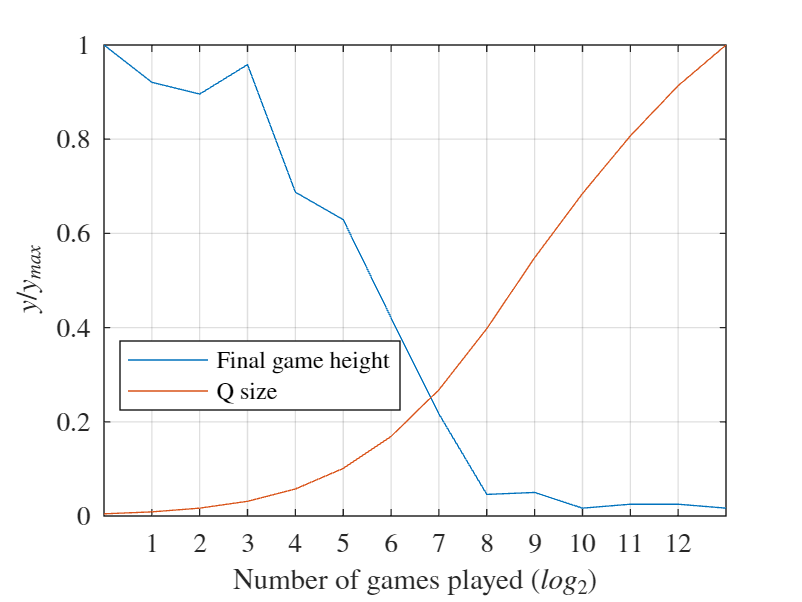


plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
%plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
%legend("Final game height", "Epsilon", "Q size")
legend("Final game height", "Q size")
xticks(1:12)
axis([0 13 0 1])

## 2 Play with reward function

The following metrics are used to calculate the reward function:

- loss (*Number of rows added to height when they're 'pushed down')*

- completed rows (number_of_completed_rows+above_row_completion)

- hole density

- bumpiness

reward = k_loss*loss + k_comp*(number_of_completed_rows+above_row_completion)

Everytime we can play with the coefficients associated to a metric

### 1 Play with loss & completed rows

The final metric will be the final/lowest height achieved after 2^11 games (not 2^13 for computation reasons)

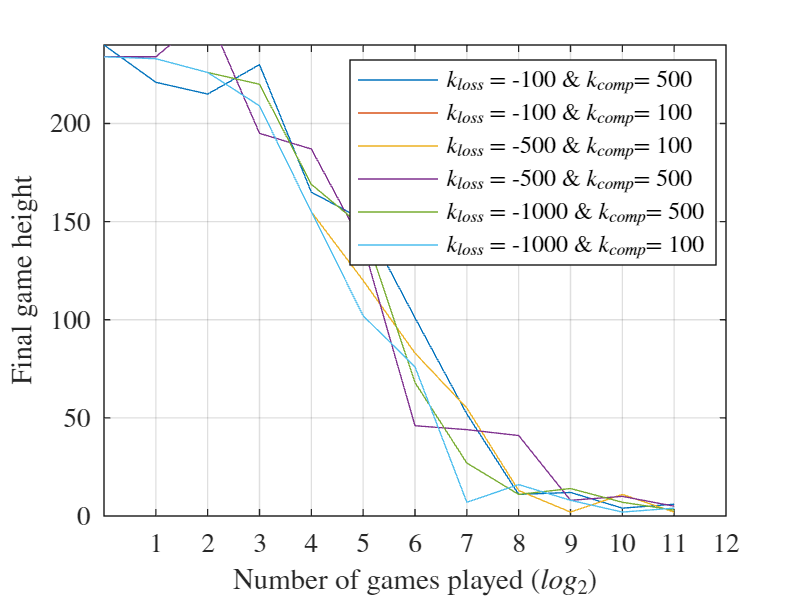

data1 = [1, 240, 0, 767
2, 221, 0, 1459
4, 215, 0, 2786
8, 230, 0, 5204
16, 165, 0, 9577
32, 151, 0, 16860
64, 101, 0, 28223
128, 52, 0, 44725
256, 11, 0, 66402
512, 12, 0, 91524
1024, 4, 0, 114256
2048, 6, 0, 134693]; % k_loss = -100 & k_comp = 500

data2 = [1, 234, 0, 749
2, 234, 0, 1456
4, 256, 0, 2784
8, 195, 0, 5214
16, 187, 0, 9597
32, 138, 0, 16945
64, 46, 0, 28378
128, 44, 0, 45087
256, 41, 0, 66298
512, 8, 0, 91393
1024, 10, 0, 114306
2048, 5, 0, 134511
]; % k_loss = -100 & k_comp = 100

data3 = [1, 234, 0, 771
2, 233, 0, 1492
4, 226, 0, 2818
8, 209, 0, 5303
16, 155, 0, 9735
32, 120, 0, 17081
64, 83, 0, 28579
128, 55, 0, 45072
256, 13, 0, 66585
512, 2, 0, 91814
1024, 11, 0, 114853
2048, 2, 0, 135636]; % k_loss = -500 & k_comp = 100

data4 = [1, 234, 0, 749
2, 234, 0, 1456
4, 256, 0, 2784
8, 195, 0, 5214
16, 187, 0, 9597
32, 138, 0, 16945
64, 46, 0, 28378
128, 44, 0, 45087
256, 41, 0, 66298
512, 8, 0, 91393
1024, 10, 0, 114306
2048, 5, 0, 134511]; % k_loss = -500 & k_comp = 500

data5 = [1, 234, 0, 771
2, 233, 0, 1492
4, 226, 0, 2818
8, 220, 0, 5322
16, 169, 0, 9759
32, 147, 0, 17163
64, 68, 0, 28687
128, 27, 0, 45292
256, 11, 0, 66619
512, 14, 0, 91824
1024, 7, 0, 114881
2048, 3, 0, 135284]; % k_loss = -1000 & k_comp = 500

data6 = [1, 234, 0, 771
2, 233, 0, 1492
4, 226, 0, 2818
8, 209, 0, 5303
16, 155, 0, 9735
32, 102, 0, 17025
64, 76, 0, 28613
128, 7, 0, 45000
256, 16, 0, 66471
512, 8, 0, 91704
1024, 2, 0, 114774
2048, 4, 0, 134958]; % k_loss = -1000 & k_comp = 100

data = zeros(12,4,2);
data(:,:,1) = data1;
data(:,:,2) = data2;
data(:,:,3) = data3;
data(:,:,4) = data4;
data(:,:,5) = data5;
data(:,:,6) = data6;

subplot
for i = 1:size(data,3)
    plot(log2(data(:,1,i)), data(:,2,i))
    hold on
end
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("Final game height")
xticks(1:12)
axis([0 12 0 max(data1(:,2))])
legend("$k_{loss}$ = -100 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -100 \& $k_{comp}$= 100", ...
    "$k_{loss}$ = -500 \& $k_{comp}$= 100", ...
    "$k_{loss}$ = -500 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -1000 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -1000 \& $k_{comp}$= 100")

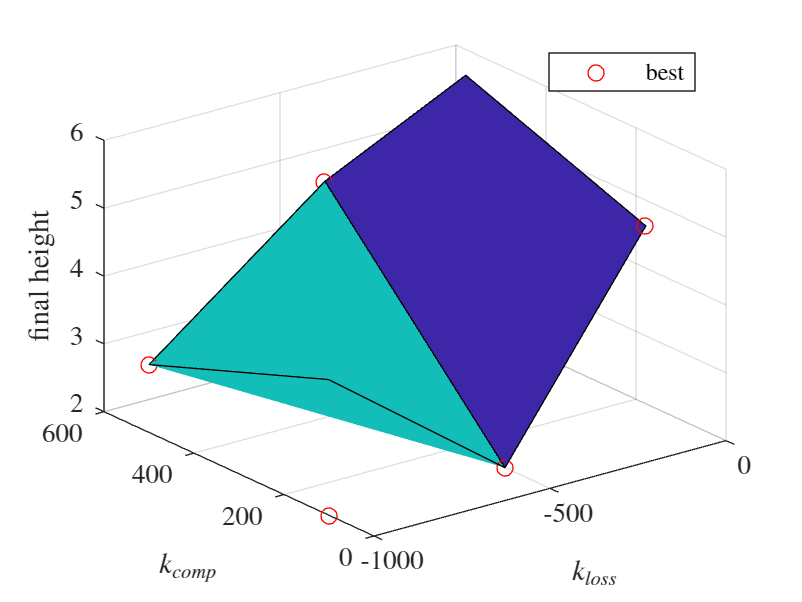


x = [-1000 -500 -100];
y = [100 500];
z = [data6(end,2) data3(end,2) data2(end,2); data5(end,2) data4(end,2) data1(end,2)];
%z2 = [min(data3(:,2)) min(data2(:,2)); min(data4(:,2)) min(data1(:,2))];
x2 = [-100 -100 -500 -500 -1000 -1000];
y2 = [500 100 100 500 500 100];
z2 = [min(data1(:,2)) min(data2(:,2)) min(data3(:,2)) min(data4(:,2)), min(data5(:,2)), min(data6(:,2))];
surf(x,y,z)
hold on
plot3(x2,y2,z2, 'ro')
hold off
xlabel("$k_{loss}$")
ylabel("$k_{comp}$")
zlabel("final height")
legend("", "best")

### 2 Play with hole density & bumpiness

(...)

## 3 Play with discount factor and learning rate

(...)

## 4 Performance metric

Final height vs evolution during the game

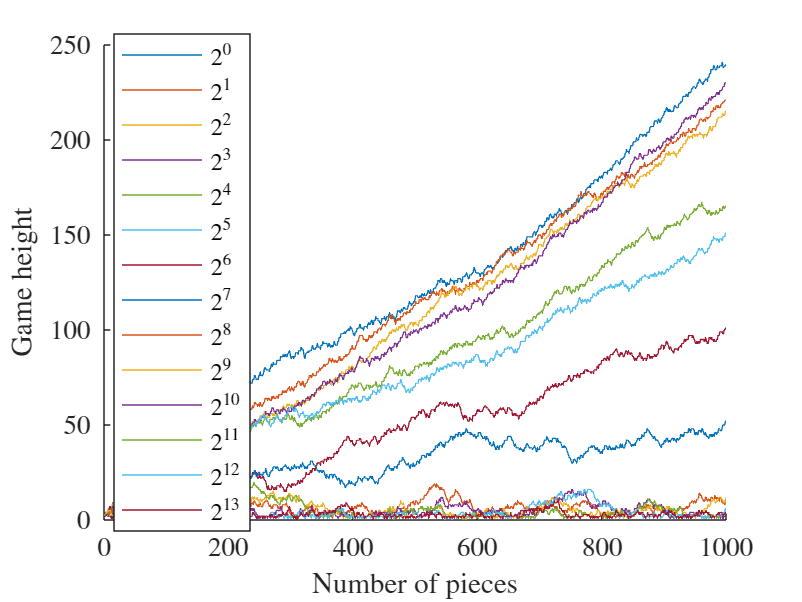

% load heights.txt
log_data = importdata('heights.txt');

figure
hold on
legend_str = cell(1, ceil(log2(size(log_data, 1))));
for i = 1:size(log_data, 1)
    if ~bitand(i, i-1) %if a power of two
        max_i = i;
        plot(1:length(log_data(i,:)),log_data(i,:))
        legend_str{log2(i)+1} = ['$2^{' num2str(log2(i)) '}$'];
    end
end
hold off

legend(legend_str(~cellfun('isempty',legend_str)))
xlabel('Number of pieces')
ylabel('Game height')

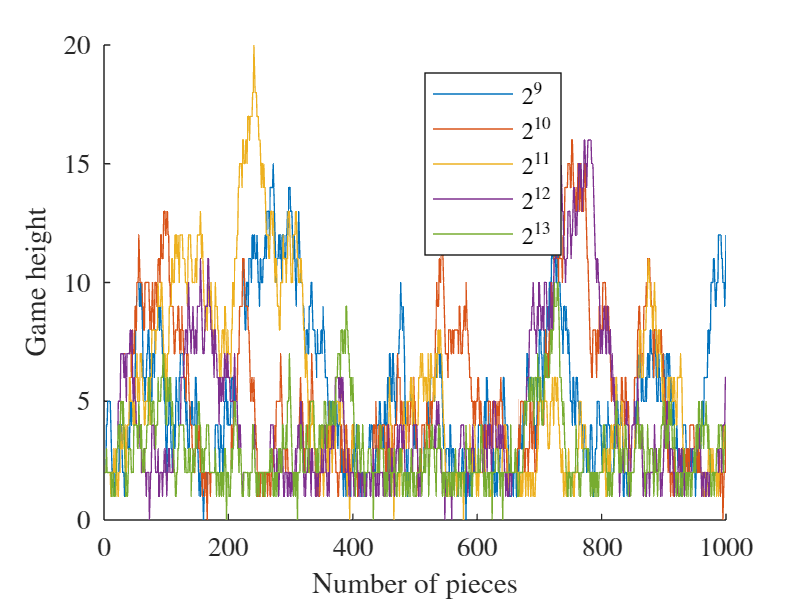


%last 5 powers of 2

figure
hold on
legend_str = cell(1, ceil(log2(size(log_data, 1))));
for i = 1:size(log_data, 1)
    if ~bitand(i, i-1) && i>2^(13-5) %if a power of two
        max_i = i;
        plot(1:length(log_data(i,:)),log_data(i,:))
        legend_str{log2(i)+1} = ['$2^{' num2str(log2(i)) '}$'];
    end
end
hold off

legend(legend_str(~cellfun('isempty',legend_str)))
xlabel('Number of pieces')
ylabel('Game height')

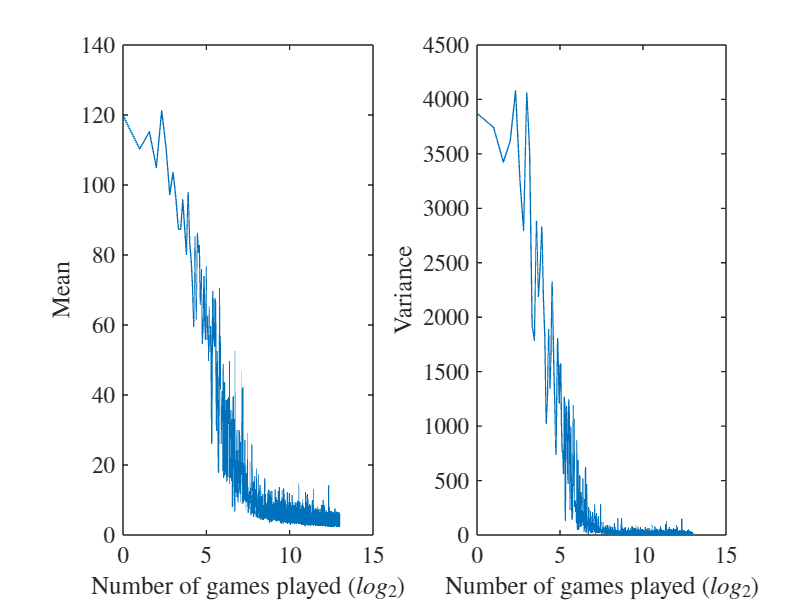


% mean and variance

mean_data = zeros(max_i,1);
var_data= zeros(max_i,1);

for i = 1:size(log_data, 1)
    mean_data(i) = mean(log_data(i,:));
    var_data(i) = var(log_data(i,:));
end

% plot((1:size(log_data, 1)), mean_data)
% ylabel("Mean")
% xlabel("Number of games played")
% 
% plot((1:size(log_data, 1)), var_data)
% ylabel("Variance")
% xlabel("Number of games played")

subplot(1,2,1)
plot(log2(1:size(log_data, 1)), mean_data)
ylabel("Mean")
xlabel("Number of games played ($log_2$)")
subplot(1,2,2)
plot(log2(1:size(log_data, 1)), var_data)
xlabel("Number of games played ($log_2$)")
ylabel("Variance")

# Discussion over the exploration method

For the following discussion we will always use the following cost function and parameters:

reward = loss*-100 + (number_of_completed_rows+above_row_completion)*500;

**float** gamma = 0.80f;*        // Discount factor*

**float** alpha = 0.02f;*        // Learning rate*

## 1 Random exploration method

exploration function = RandomExplorationMethod

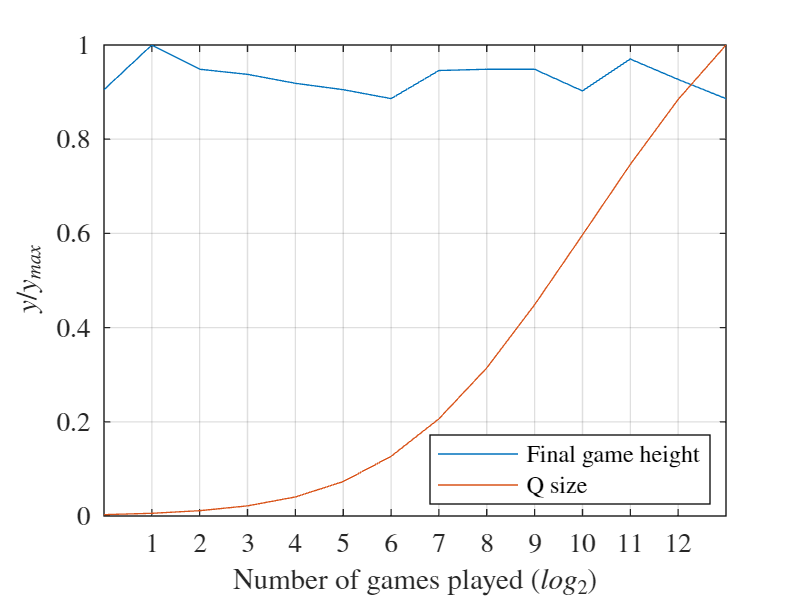

data1 = [1, 334, 0, 803
2, 369, 0, 1595
4, 350, 0, 3137
8, 346, 0, 5979
16, 339, 0, 11252
32, 334, 0, 20314
64, 327, 0, 35218
128, 349, 0, 57371
256, 350, 0, 87427
512, 350, 0, 124718
1024, 333, 0, 165909
2048, 358, 0, 207577
4096, 342, 0, 245911
8192, 327, 0, 278052];

figure
plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
%plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
%legend("Final game height", "Epsilon", "Q size")
legend("Final game height", "Q size")
xticks(1:12)
axis([0 13 0 1])

## 2 Epsilon greedy exploration method

### 1 Basic

epsilon = 0.1 and no decay

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))

Index in position 2 exceeds array bounds.

hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")


### 2 Play with epsilon

epsilon = 0:0.1:0.9 and no decay

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")


### 3 Play with decay

epsilon = 0.2 and decay

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")

## 3 Simple exploration method

### 1 Basic

 **int** N_MAX = 10;

 **double** R_PLUS = 20.0;

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")

### 2 Play with Nmax & Rplus

(...)

# Computing time, convergence rate, stability, ...

(...)